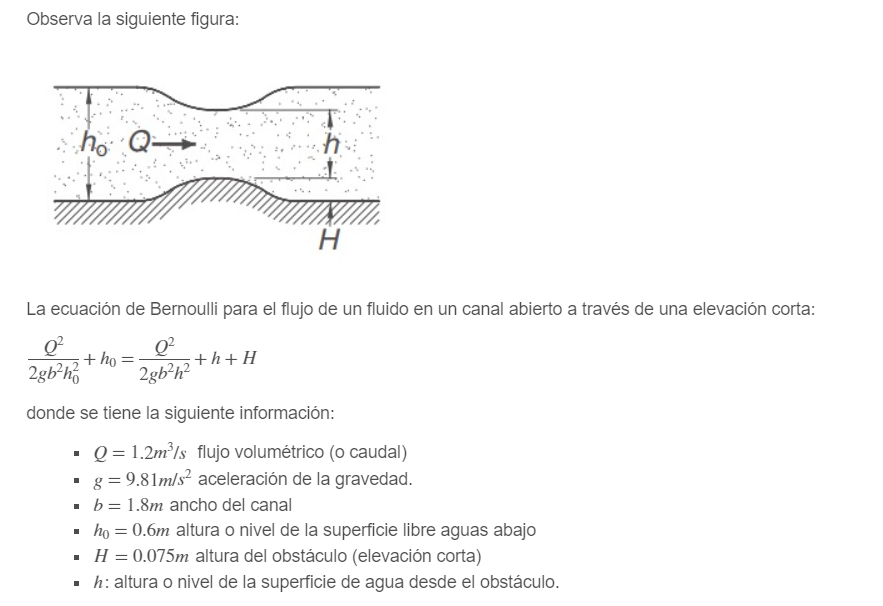

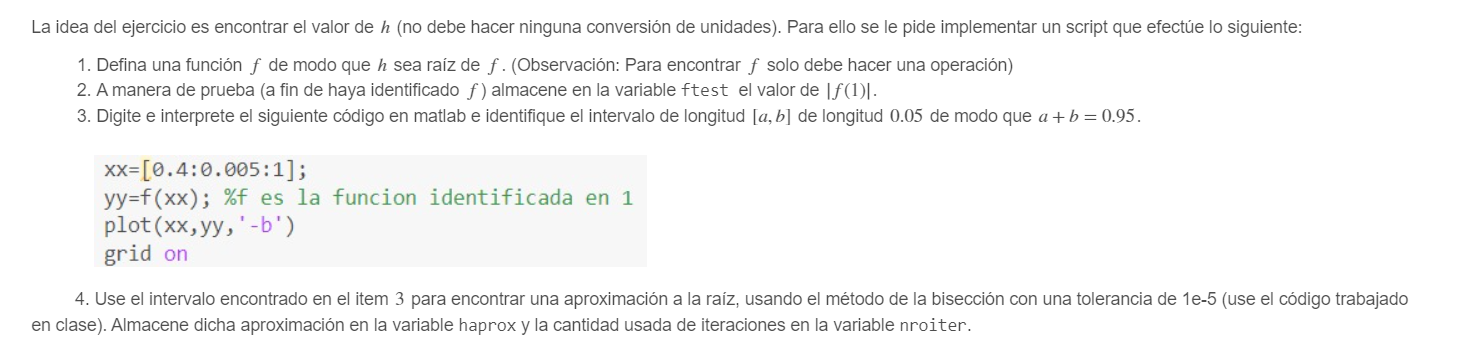

syms h
f= @(h)((((1.2^2)./(2*9.81*(1.8^2)*(h.^2)))+h+0.075)-(((1.2^2)/(2*9.81*(1.8^2)*(0.6^2)))+0.6))

f = function_handle with value:
    @(h)((((1.2^2)./(2*9.81*(1.8^2)*(h.^2)))+h+0.075)-(((1.2^2)/(2*9.81*(1.8^2)*(0.6^2)))+0.6))


f(h)

$$ans = h+\frac{200}{8829\,h^{2}}-\frac{13238870413275579}{22517998136852480}$$

ftest=abs(f(1)) %pasó el pretest

ftest = 0.4347


%Solución dudosa desde acá :'(((
xx=[0.4:0.05:1]

xx =     0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


yy=f(xx)

yy =    -0.0463   -0.0261    0.0027    0.0370    0.0750    0.1157    0.1583    0.2023    0.2475    0.2934    0.3400    0.3872    0.4347


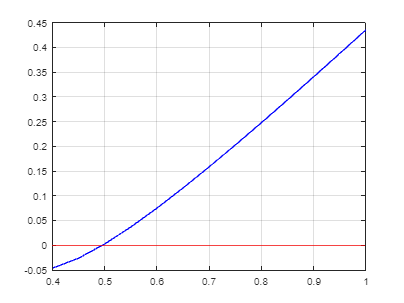

plot(xx,yy,'-b')
grid on
yline(0,'red')


fzero(f,0.5)

ans = 0.4958

fzero(f,0.45)

ans = 0.4958


Tol=1e-5

Tol = 1.0000e-05

z=biseccion2(f,0.45,0.5,Tol)

Se necesita 12 iteraciones


z =     0.4500    0.5000    0.4750   -0.0261    0.0027   -0.0125    0.0250
    0.4750    0.5000    0.4875   -0.0125    0.0027   -0.0051    0.0125
    0.4875    0.5000    0.4938   -0.0051    0.0027   -0.0013    0.0063
    0.4938    0.5000    0.4969   -0.0013    0.0027    0.0007    0.0031
    0.4938    0.4969    0.4953   -0.0013    0.0007   -0.0003    0.0016
    0.4953    0.4969    0.4961   -0.0003    0.0007    0.0002    0.0008
    0.4953    0.4961    0.4957   -0.0003    0.0002   -0.0000    0.0004
    0.4957    0.4961    0.4959   -0.0000    0.0002    0.0001    0.0002
    0.4957    0.4959    0.4958   -0.0000    0.0001    0.0000    0.0001
    0.4957    0.4958    0.4958   -0.0000    0.0000   -0.0000    0.0000


z(end,3)

ans = 0.4958

function z=biseccion2(f,a,b,Tol)
c=(a+b)/2;
error=(b-a)/2;
z=[a b c f(a) f(b) f(c) error];
N=ceil(log((b-a)/(2*Tol))/log(2));
fprintf('Se necesita %d iteraciones\n',N)
while error>Tol
if f(a)*f(c)<0
b=c;
else
a=c;
end
c=(a+b)/2;
error=(b-a)/2;
z=[z; a b c f(a) f(b) f(c) error];
end
end

